# Medical Image Processing - Final Project

## **Authors: **

- **Javier Sanguino Alcolado**

- **Max Witwer **

- **Braden Schweer**

- **Melanie Werzi**

- **Tobias Haider**

## Preparation

### Load the scripts

addpath("script/NIFTI_reader");
addpath("script/segmentation");
addpath("script/segmentation/plot");
addpath("script/morphological_filters/");

### Import images

ct_lungs_noise = load_nii('data/CT_lungs_noise.nii');
ct_lungs = load_nii('data/CT_lungs.nii');
ct = load_nii('data/CT.nii');
pet = load_nii('data/PET.nii');

## Image Segmentation

### Exercise 1: Segment the images with Otsu

ct_segmentation = otsu_segmentation(ct.img);
pet_segmentation = otsu_segmentation(pet.img);

#### Exercise 1: Alternative Otsu implementation

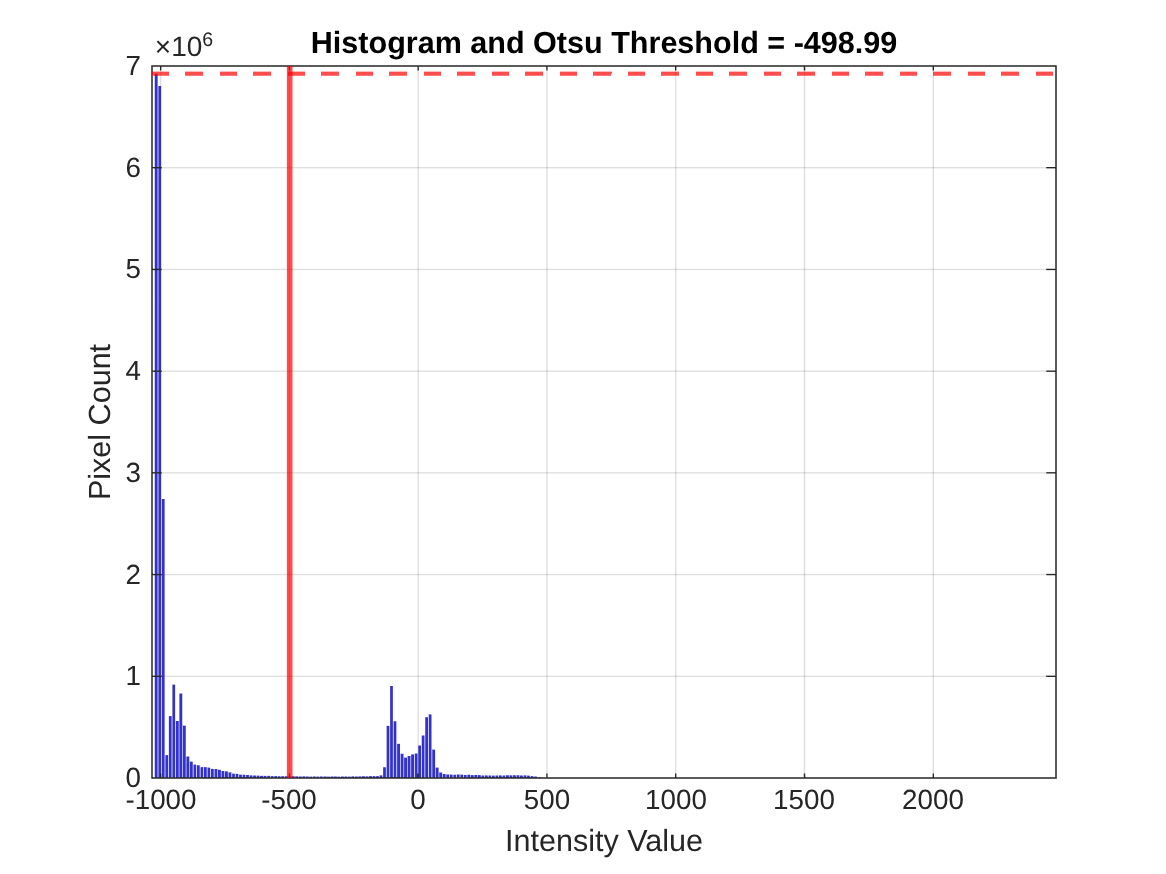

[ct_threshold, CTmask, ct_hist, ct_time] = otsu_segmentation2(ct.img, true);

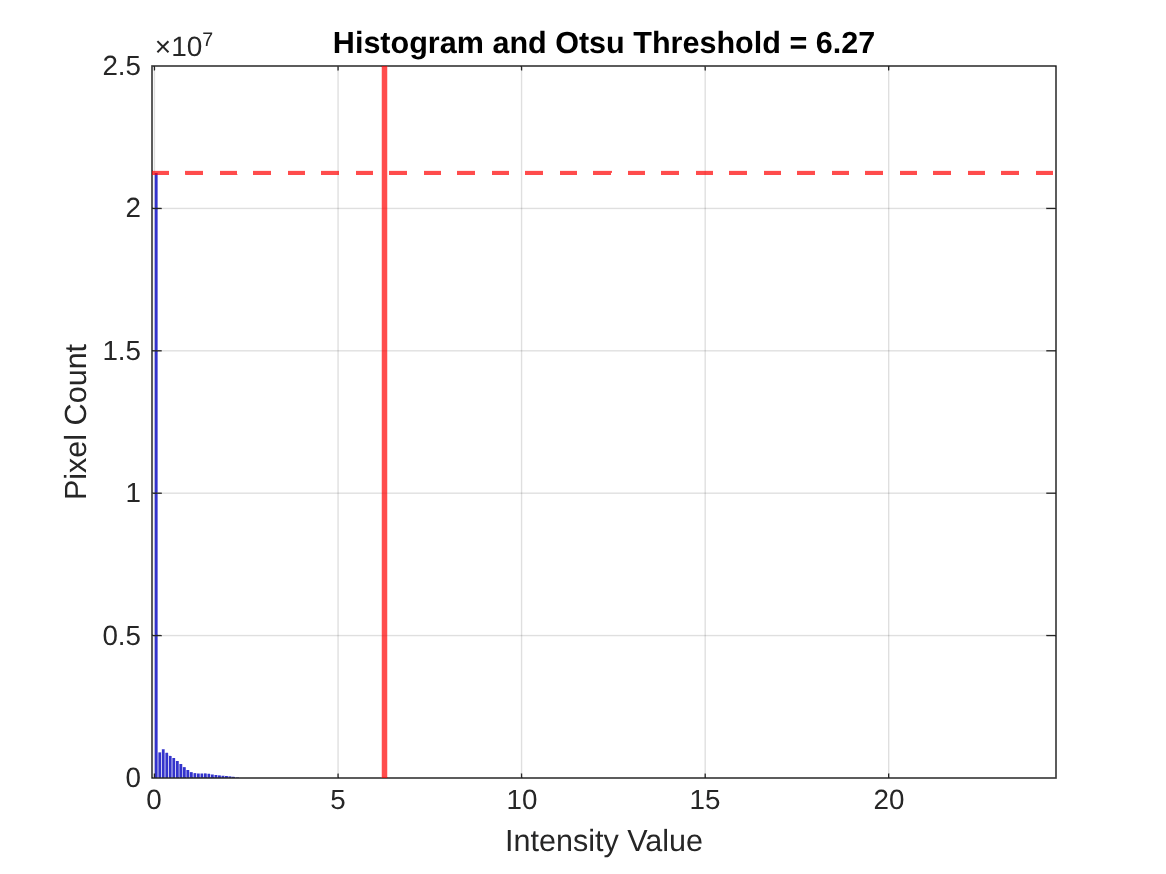

[pet_threshold, PETmask, pet_hist, pet_time] = otsu_segmentation2(pet.img, true);

fprintf('CT threshold: %.2f\nCT time: %.2f\n', ct_threshold, ct_time);

CT threshold: -498.99
CT time: 0.07


fprintf('PET threshold: %.2f\nPET time: %.2f\n', pet_threshold, pet_time);

PET threshold: 6.27
PET time: 0.06


### Exercise 2: Plot the segmentation result

#### CT

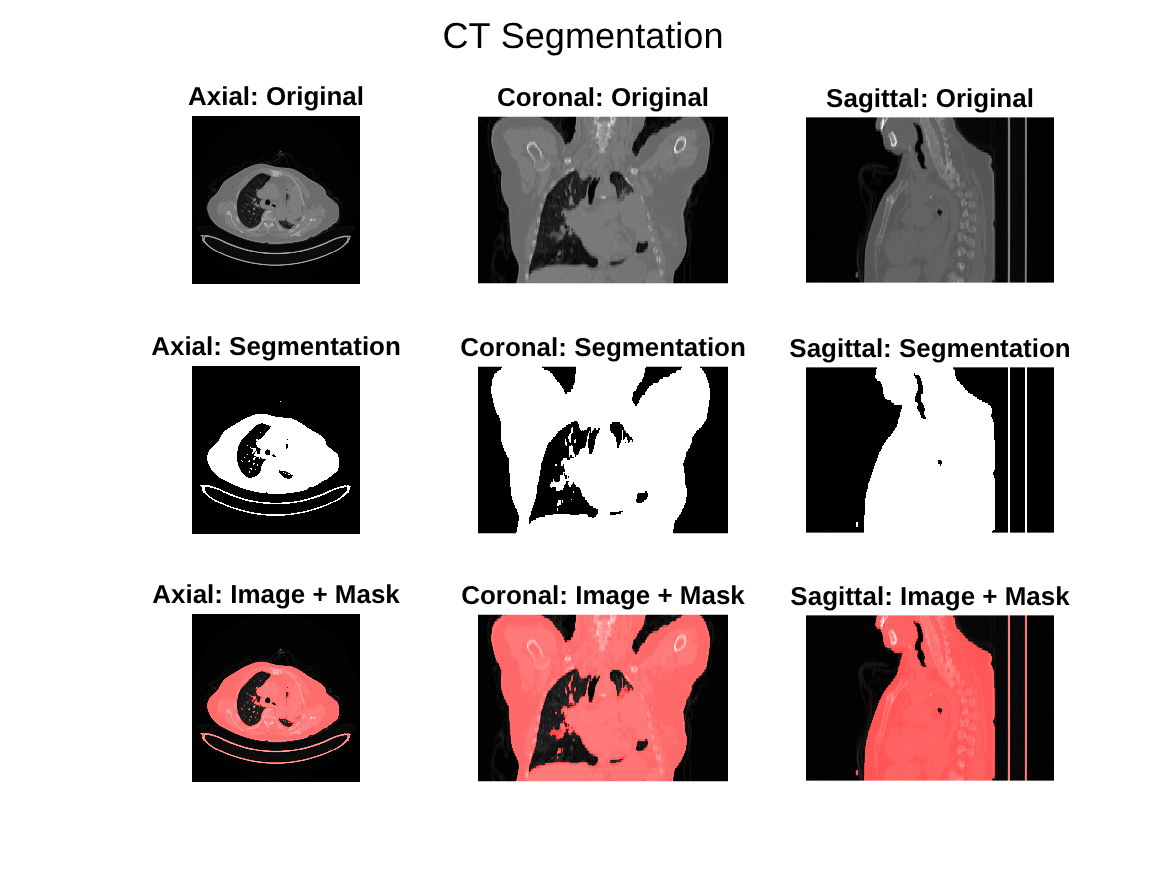

plot_segmentation(ct.img, ct_segmentation, ct.hdr.dime.pixdim(2:4));
sgtitle("CT Segmentation");

#### PET

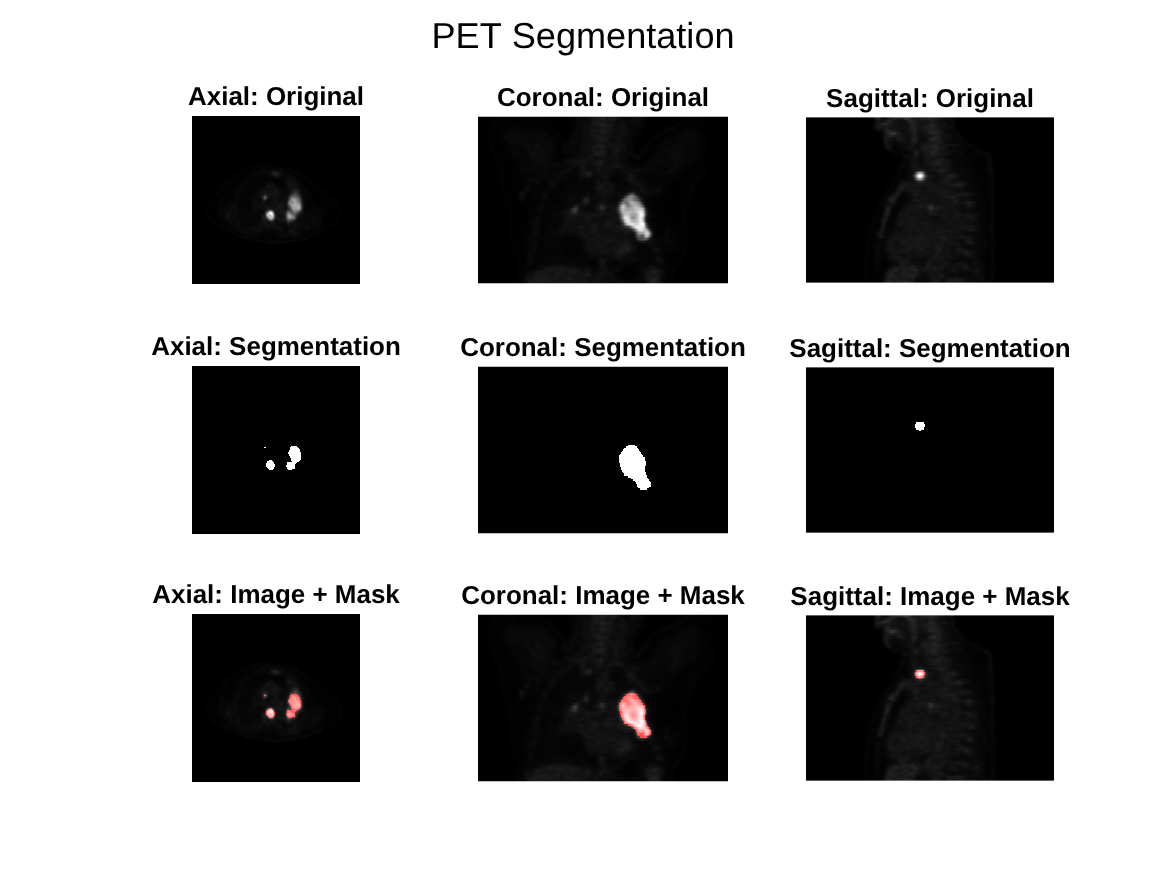

plot_segmentation(pet.img, pet_segmentation, pet.hdr.dime.pixdim(2:4));
sgtitle("PET Segmentation");

## Morphological Filters

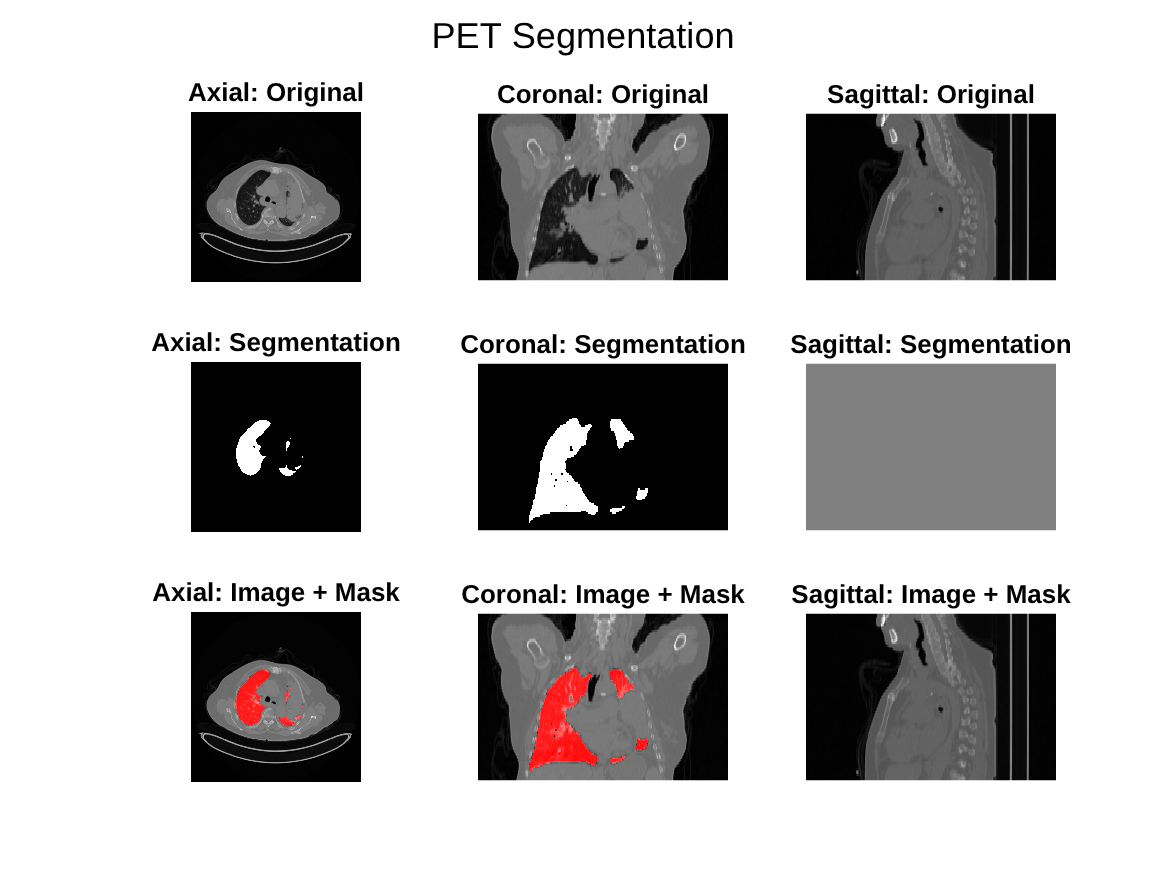

% Without removing noise
plot_segmentation(ct.img, ct_lungs_noise.img, ct_lungs.hdr.dime.pixdim(2:4));

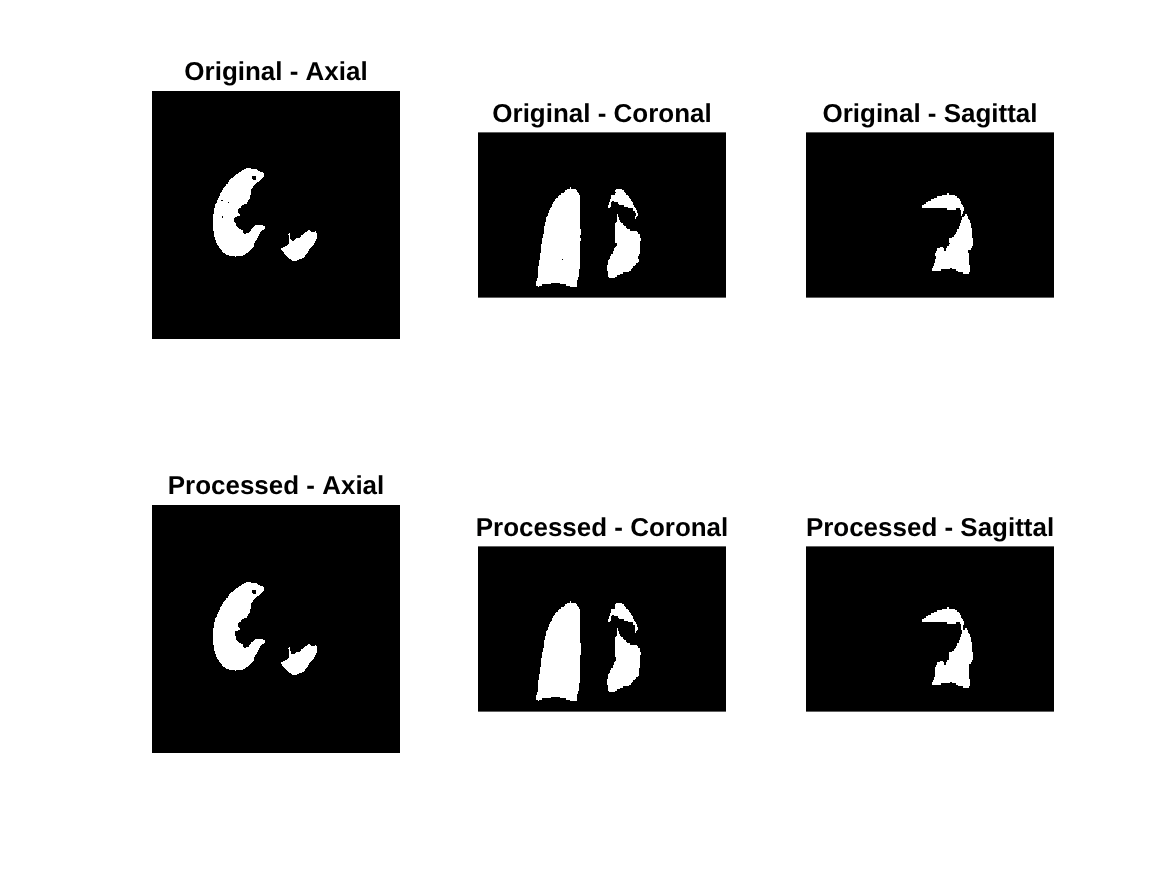

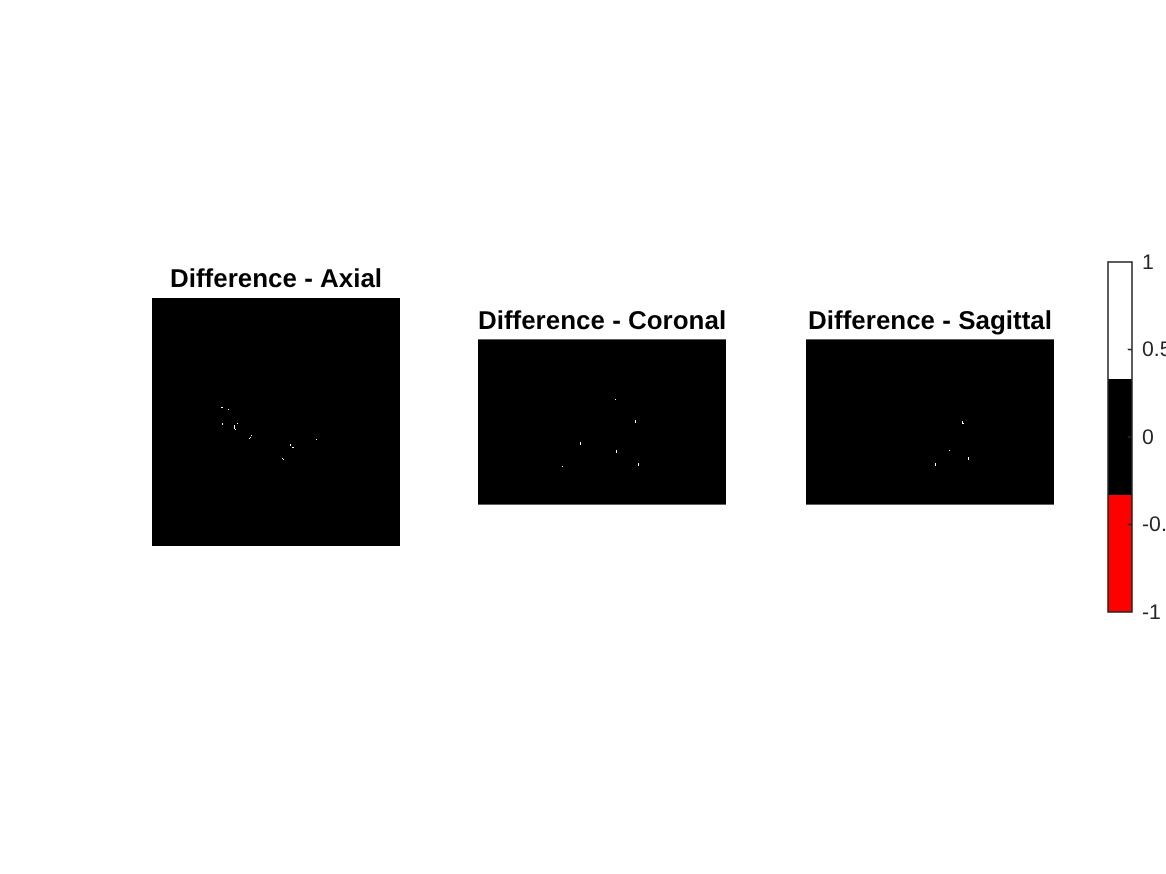

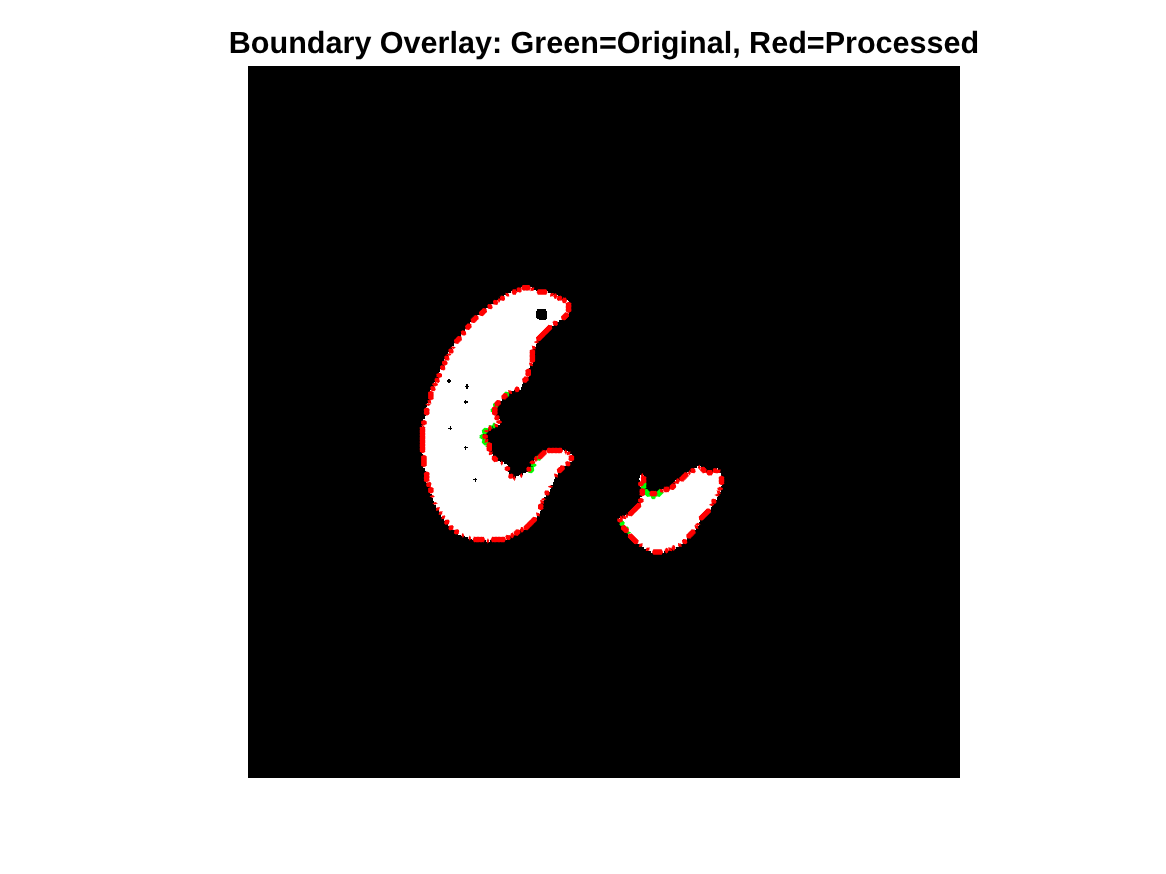

% Closing noise with cube of 3px
se = strel('cube', 3);
mask_closed_cube = imclose(ct_lungs_noise.img, se);
analyse_morphological_filter(ct_lungs_noise.img, mask_closed_cube, [200,200,40], ct_lungs_noise.hdr.dime.pixdim(2:4));

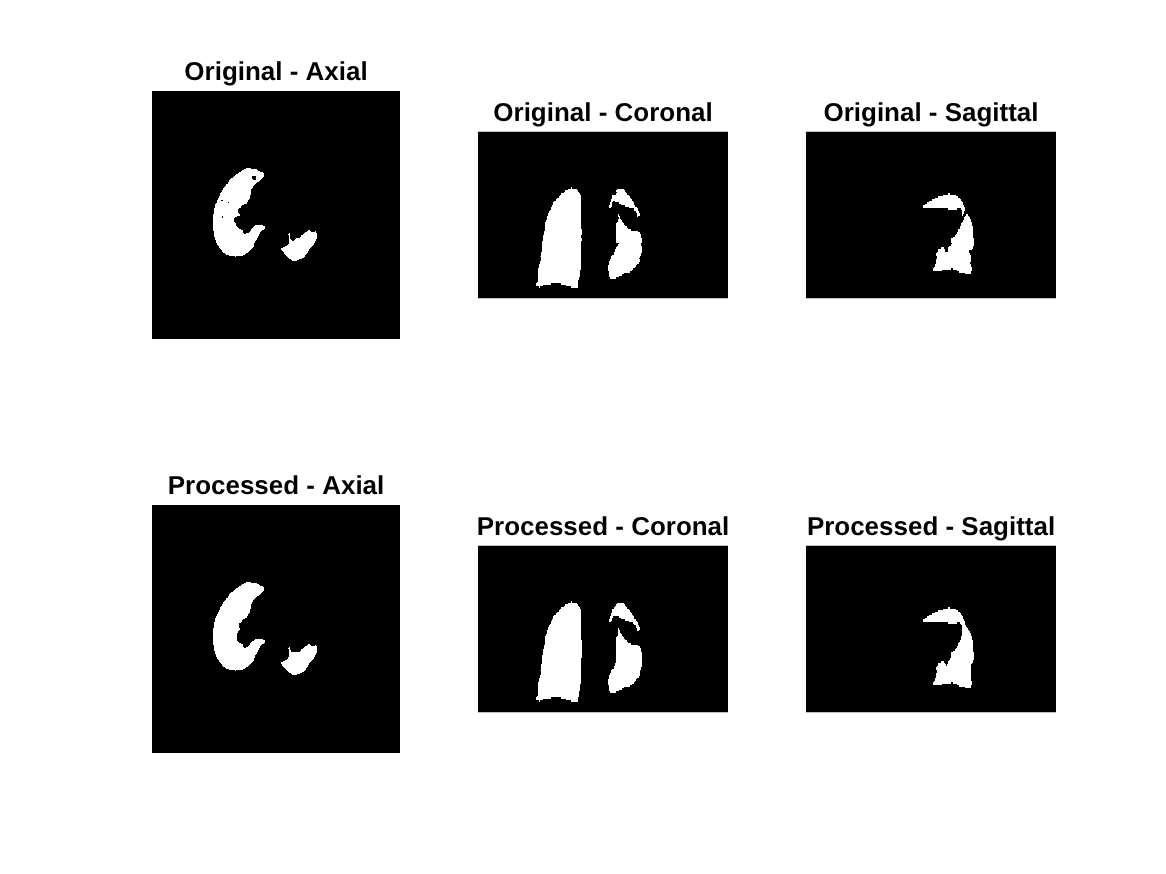

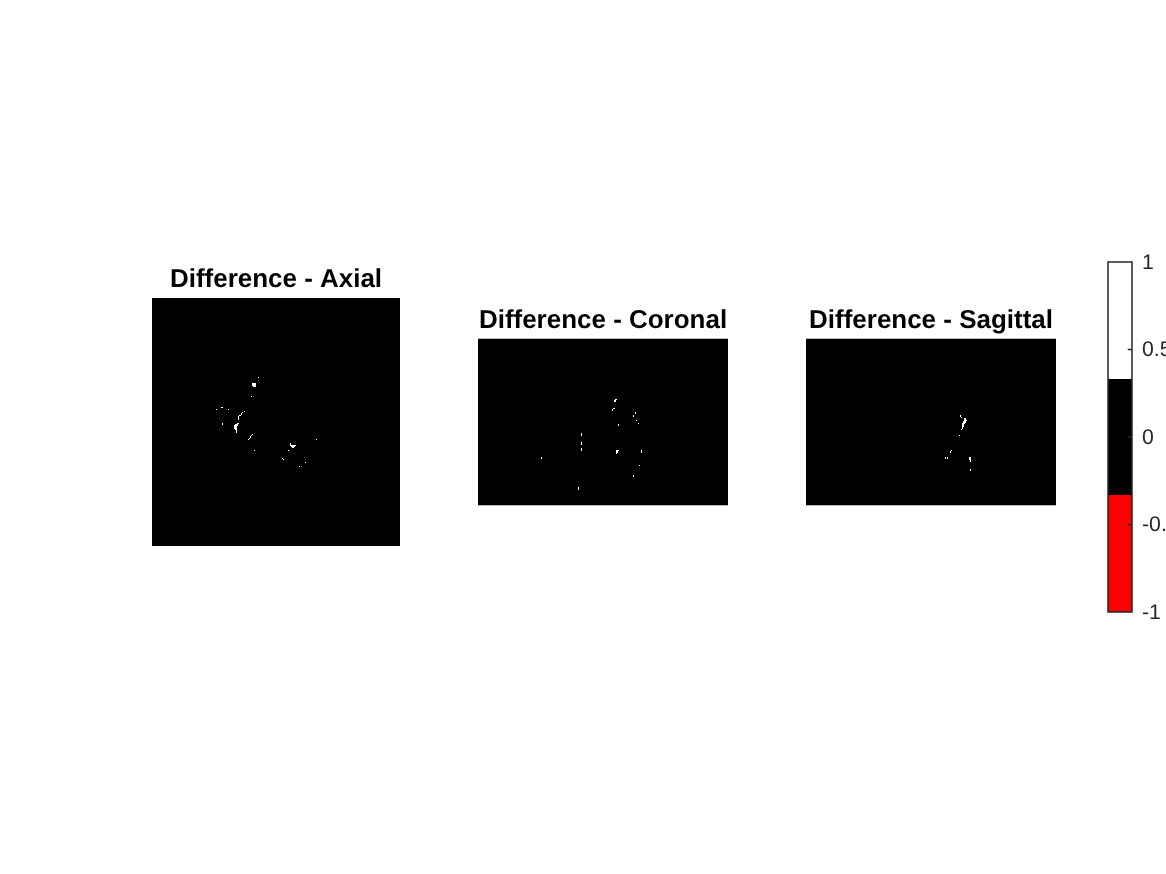

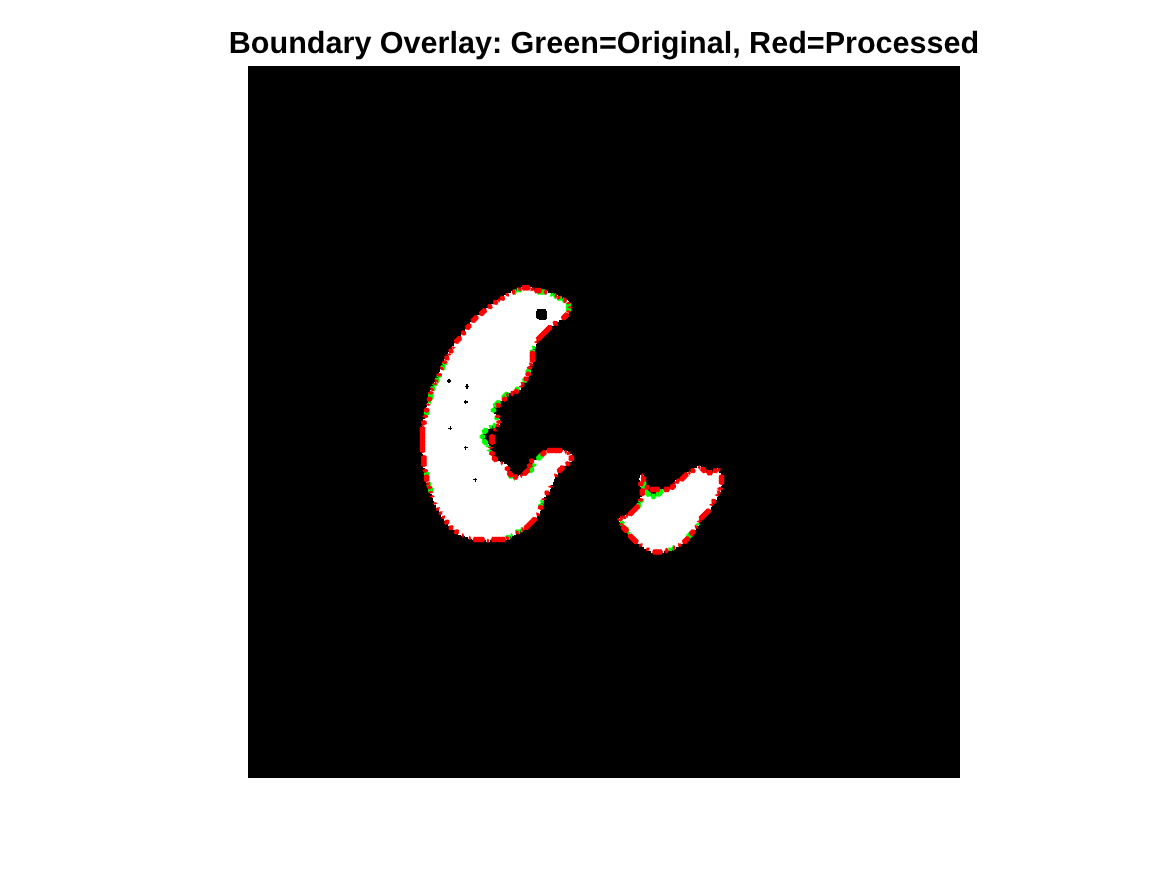

% Closing noise with sphere of 3px
se = strel('sphere', 3);
mask_closed_sphere = imclose(ct_lungs_noise.img, se);
analyse_morphological_filter(ct_lungs_noise.img, mask_closed_sphere, [200,200,40], ct_lungs_noise.hdr.dime.pixdim(2:4));

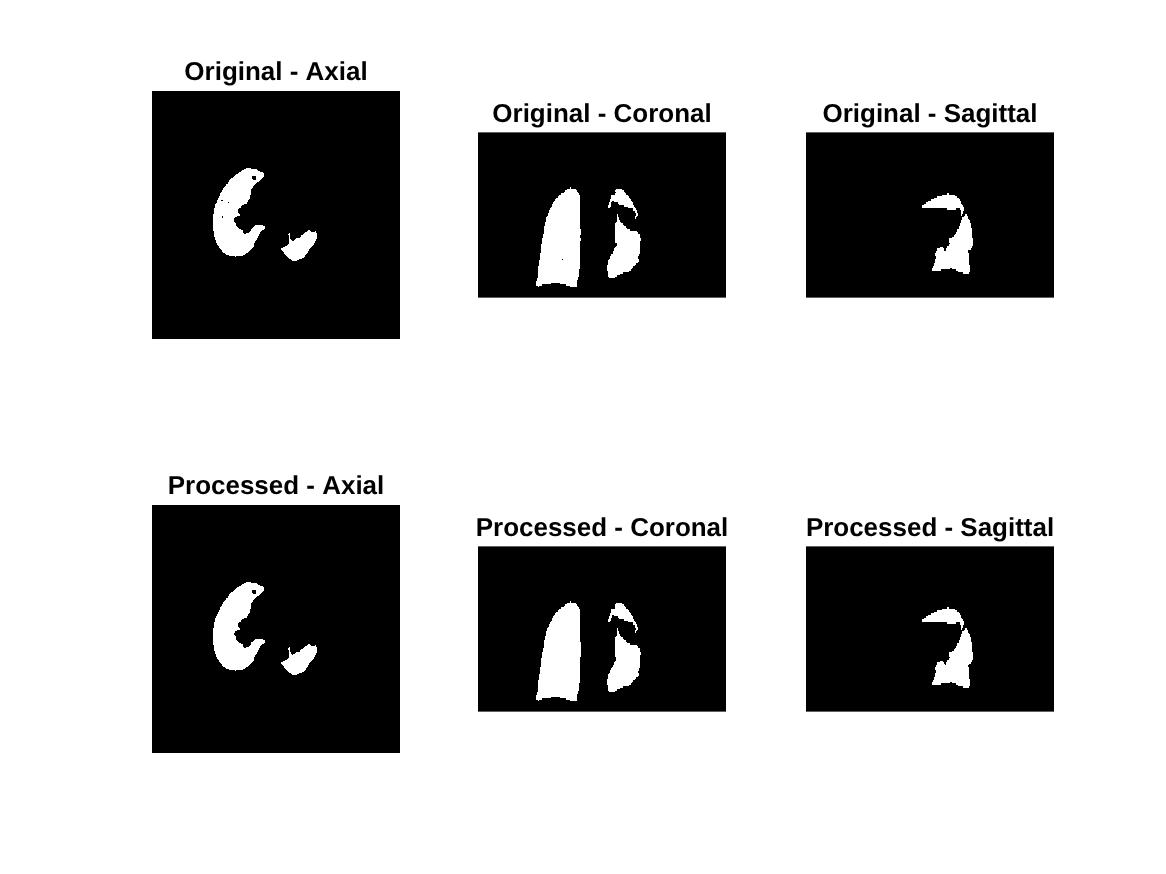

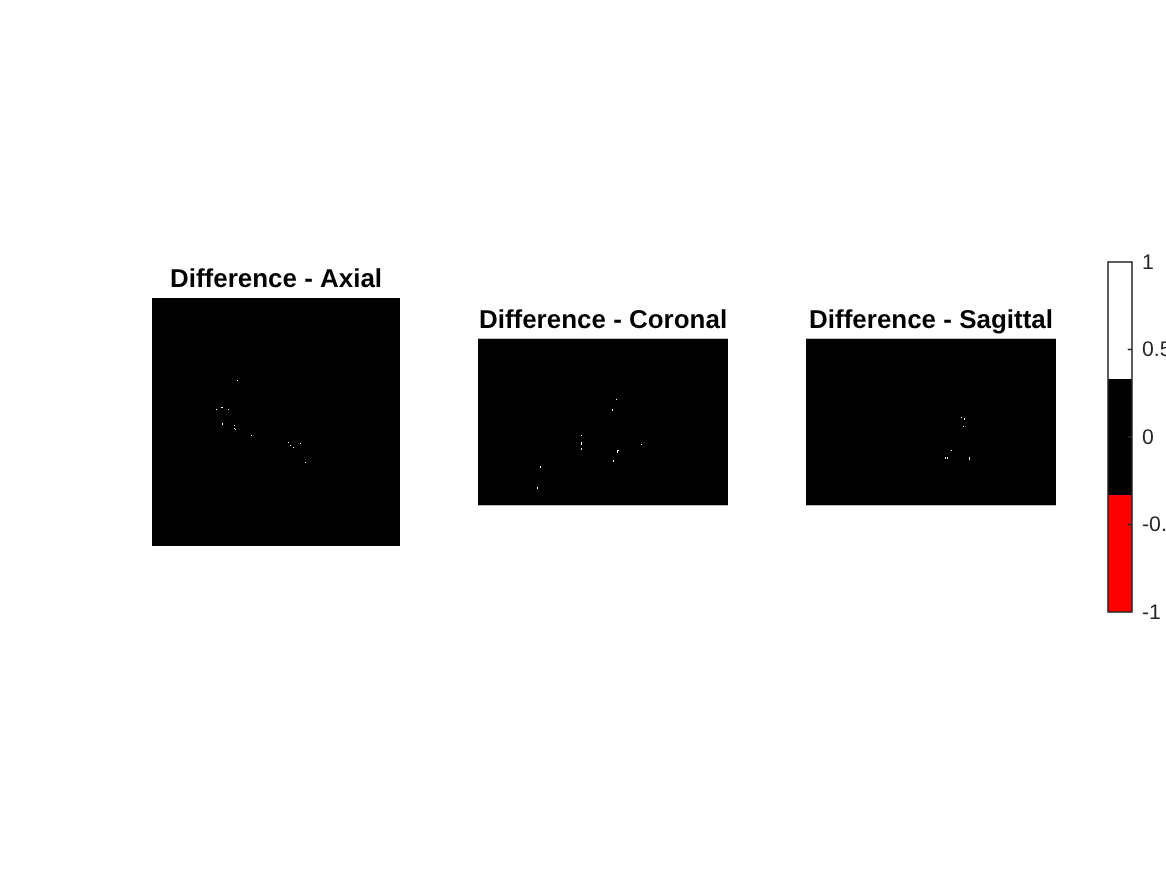

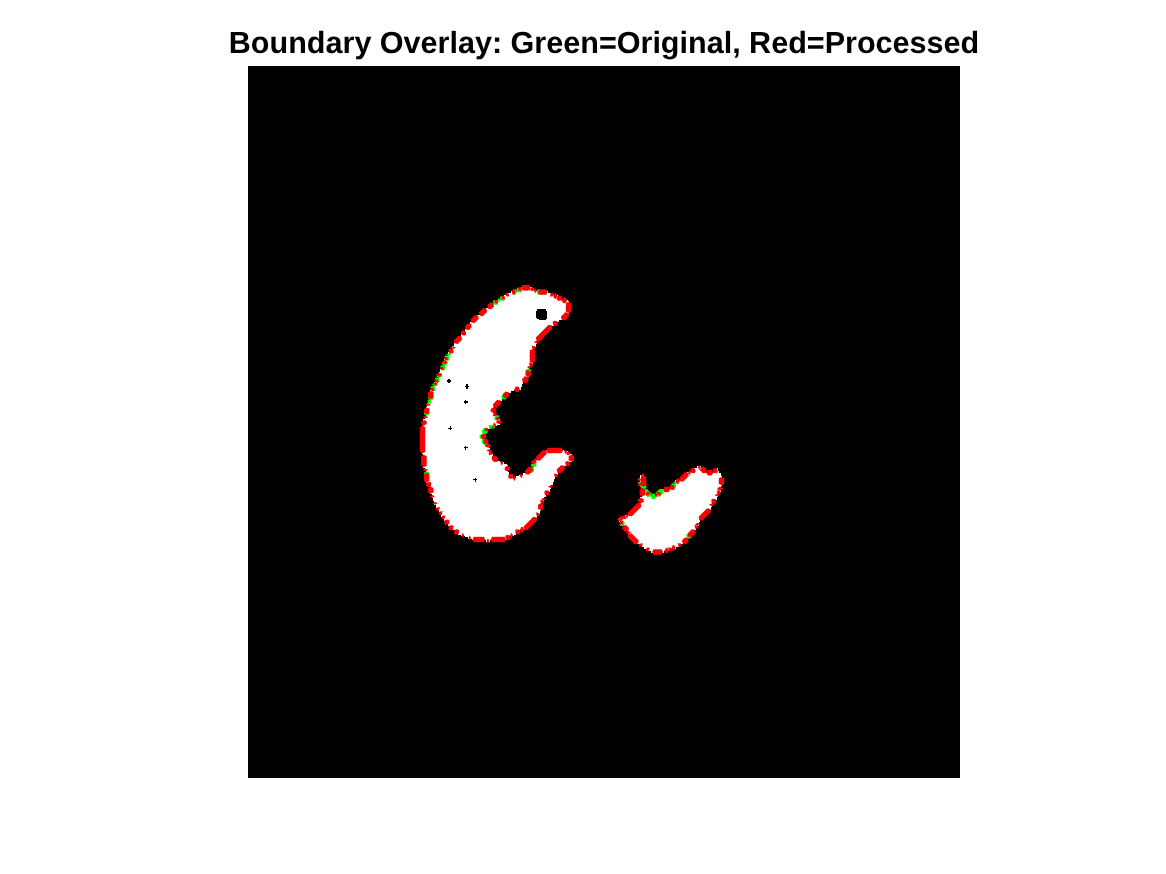

% Closing noise with sphere of 1px
se = strel('sphere', 1);
mask_closed_sphere = imclose(ct_lungs_noise.img, se);
analyse_morphological_filter(ct_lungs_noise.img, mask_closed_sphere, [200,200,40], ct_lungs_noise.hdr.dime.pixdim(2:4));

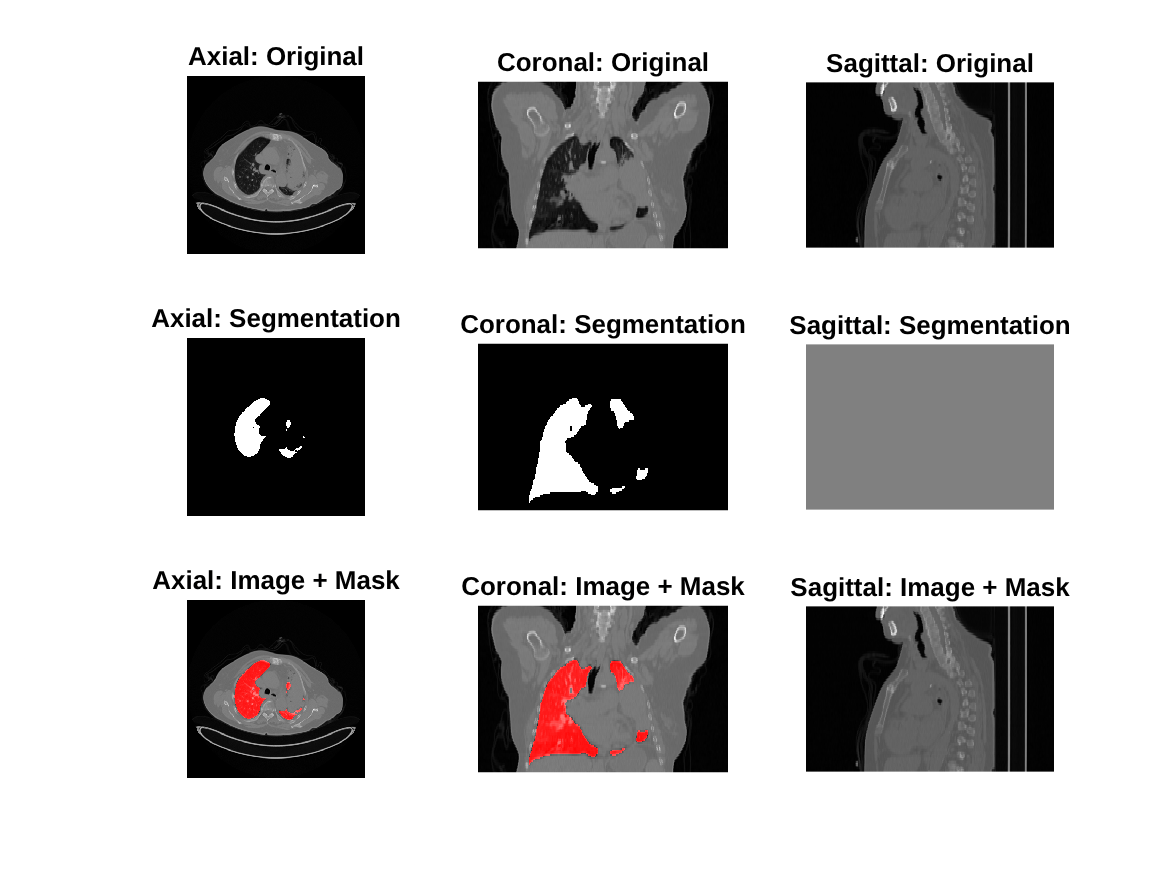


figure;
plot_segmentation(ct.img, mask_closed_sphere, ct.hdr.dime.pixdim(2:4));

## Exercise 4: Calculating Statistics

function quantify_ct_pet(CT_img, PET_img, CTmask, PETmask, CTlungs_noise, CTlungs_filtered, pixel_size)

CTmask:
Volume (mm^3): 20564105.99
Avg CT Gray Value: -13.72
Avg PET Gray Value: 0.83

PETmask:
Volume (mm^3): 254302.02
Avg CT Gray Value: 39.26
Avg PET Gray Value: 12.40

CTlungs_noise:
Volume (mm^3): 2399159.43
Avg CT Gray Value: -694.03
Avg PET Gray Value: 0.61

CTlungs_filtered:
Volume (mm^3): 2409436.23
Avg CT Gray Value: -692.70
Avg PET Gray Value: 0.61




    % Compute the voxel volume in mm^3
    voxel_volume = pixel_size(1) * pixel_size(2) * pixel_size(3);

    % Process CTmask
    CTmask = logical(CTmask);
    voxels_CTmask = sum(CTmask(:));
    volume_CTmask = voxels_CTmask * voxel_volume;
    avg_CT_CTmask = mean(CT_img(CTmask));
    avg_PET_CTmask = mean(PET_img(CTmask));
    fprintf('CTmask:\n');
    fprintf('Volume (mm^3): %.2f\n', volume_CTmask);
    fprintf('Avg CT Gray Value: %.2f\n', avg_CT_CTmask);
    fprintf('Avg PET Gray Value: %.2f\n\n', avg_PET_CTmask);

    % Process PETmask
    PETmask = logical(PETmask);
    voxels_PETmask = sum(PETmask(:));
    volume_PETmask = voxels_PETmask * voxel_volume;
    avg_CT_PETmask = mean(CT_img(PETmask));
    avg_PET_PETmask = mean(PET_img(PETmask));
    fprintf('PETmask:\n');
    fprintf('Volume (mm^3): %.2f\n', volume_PETmask);
    fprintf('Avg CT Gray Value: %.2f\n', avg_CT_PETmask);
    fprintf('Avg PET Gray Value: %.2f\n\n', avg_PET_PETmask);

    % Process CTlungs_noise
    CTlungs_noise = logical(CTlungs_noise);
    voxels_lungs_noise = sum(CTlungs_noise(:));
    volume_lungs_noise = voxels_lungs_noise * voxel_volume;
    avg_CT_lungs_noise = mean(CT_img(CTlungs_noise));
    avg_PET_lungs_noise = mean(PET_img(CTlungs_noise));
    fprintf('CTlungs_noise:\n');
    fprintf('Volume (mm^3): %.2f\n', volume_lungs_noise);
    fprintf('Avg CT Gray Value: %.2f\n', avg_CT_lungs_noise);
    fprintf('Avg PET Gray Value: %.2f\n\n', avg_PET_lungs_noise);

    % Process CTlungs_filtered
    CTlungs_filtered = logical(CTlungs_filtered);
    voxels_lungs_filtered = sum(CTlungs_filtered(:));
    volume_lungs_filtered = voxels_lungs_filtered * voxel_volume;
    avg_CT_lungs_filtered = mean(CT_img(CTlungs_filtered));
    avg_PET_lungs_filtered = mean(PET_img(CTlungs_filtered));
    fprintf('CTlungs_filtered:\n');
    fprintf('Volume (mm^3): %.2f\n', volume_lungs_filtered);
    fprintf('Avg CT Gray Value: %.2f\n', avg_CT_lungs_filtered);
    fprintf('Avg PET Gray Value: %.2f\n\n', avg_PET_lungs_filtered);
end






% Call the function
quantify_ct_pet(ct.img, pet.img, ct_segmentation, pet_segmentation, ct_lungs_noise.img, mask_closed_sphere, ct.hdr.dime.pixdim(2:4));
